% Create tranfer function.
s=tf('s');
Gopen=30*(s+1)/(s*(s+5)*(s^2+4*s+6))


Gopen =
 
           30 s + 30
  ---------------------------
  s^4 + 9 s^3 + 26 s^2 + 30 s
 
Continuous-time transfer function.



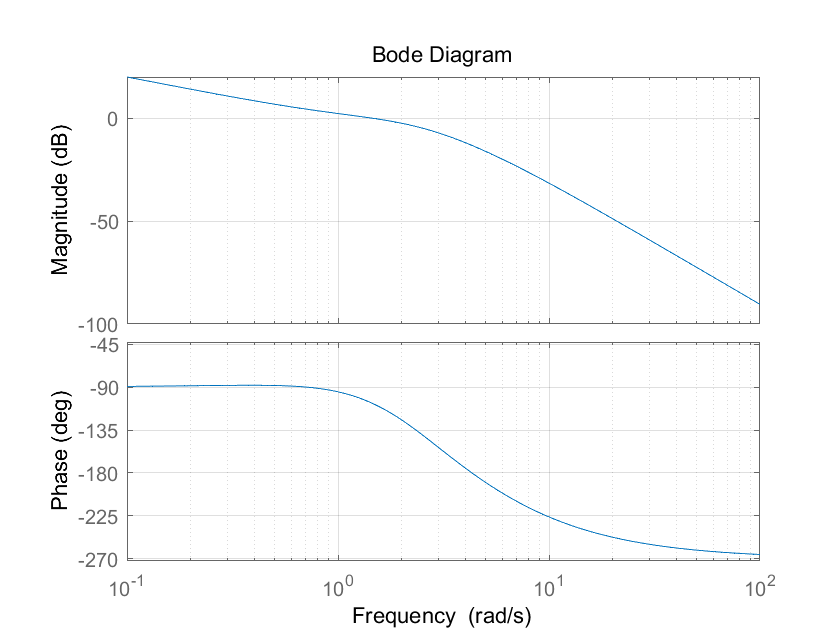


% Create a list of number with 50 numbers 
% arrange evenly between 10^0 and 10^4 in log space
w=logspace(-1,2,100);

% Draw the bode chart of the system
bode(Gopen,w);
grid on;


% Am --- Ampitude margin
% Pm --- Phase margin
% Wc --- Cutoff frequency
% Wg --- Traverse frequency
[Am,Pm,Wc,Wg]=margin(Gopen);

fprintf('The ampitude margin of the system is %f dB\n', 20*log10(Am));

The ampitude margin of the system is 13.234179 dB


fprintf('\tThe cutoff frequency is %f rad/s\n', Wc);

	The cutoff frequency is 4.316478 rad/s


fprintf('The phase margin of the system is %f degrees\n', Pm);

The phase margin of the system is 73.045557 degrees


fprintf('\tThe traverse frequency is %f rad/s\n', Wg);

	The traverse frequency is 1.452999 rad/s
